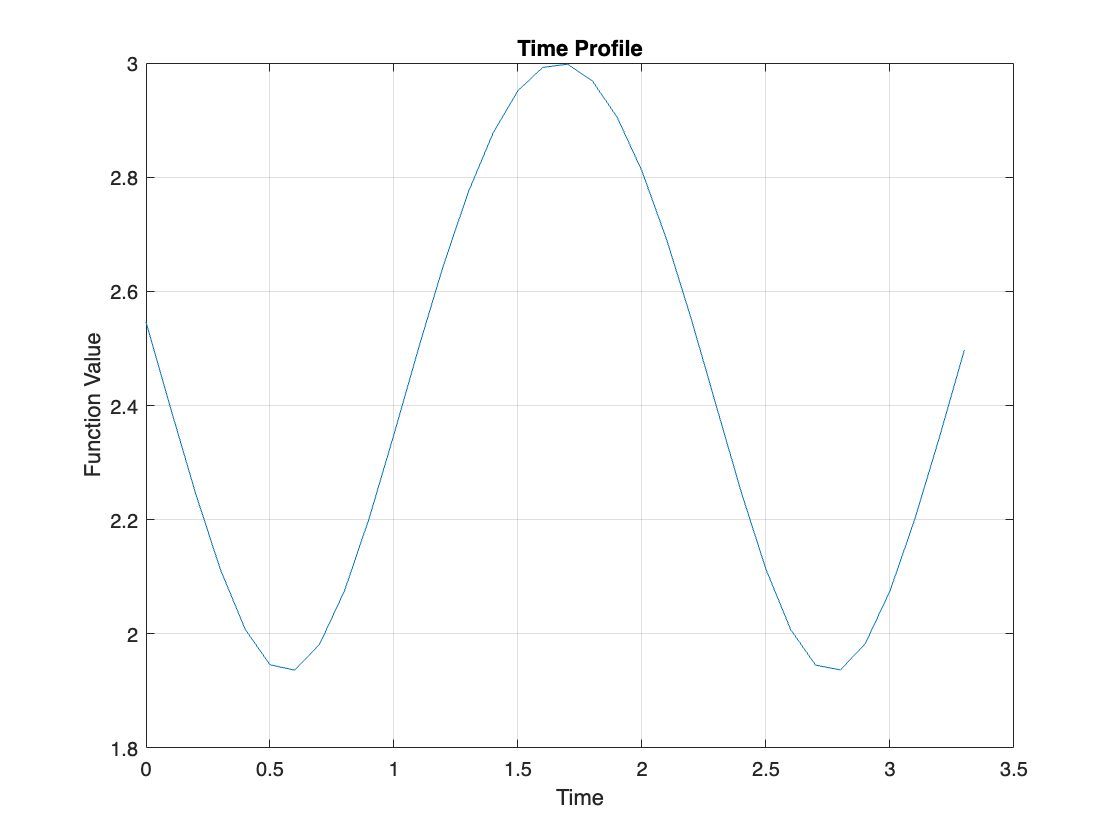

clear;
R = 1.5;
A = 3;
T = double(3 * sym(pi) / 2 * sqrt(R / A));
t = 0:0.1:T;
tau = t / T;

alpha = 36 * sym(pi) ^ 2 .* (tau .* (1 - tau)) .^ 4 + (2 .* tau - 1) .^ 2;

norm_p_dot_dot = 6 * R * sym(pi) / T ^ 2 * sqrt(alpha);

y = norm_p_dot_dot;

% Plotting the time profile
plot(t, y)
title('Time Profile')
xlabel('Time')
ylabel('Function Value')
grid on

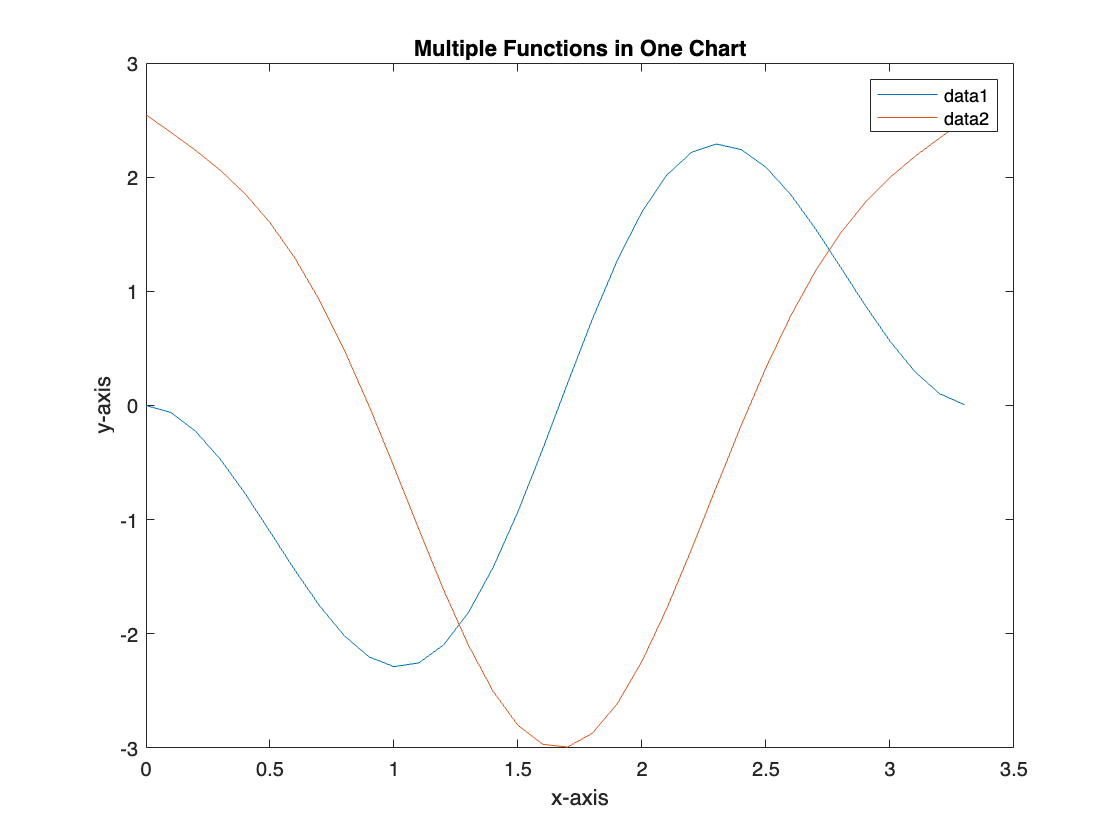

s = sym(pi) .* (3 .* tau .^ 2 - 2 .* tau .^ 3);
s_dot = 6 * sym(pi) / T .* (tau - tau .^ 2);
s_dot_dot = 6 * sym(pi) / T ^ 2 .* (1 - 2 .* tau);

p_dot_dot = -R * [cos(s); sin(s)] .* s_dot .^ 2 + R * [-sin(s); cos(s)] .* s_dot_dot;

% Plot each function on the same chart
figure;
plot(t, p_dot_dot(1, :));
hold on;  % This keeps the current plot and adds the next one
plot(t, p_dot_dot(2, :));

% Add labels and legend
xlabel('x-axis');
ylabel('y-axis');
title('Multiple Functions in One Chart');
legend('show');
hold off;  % Release the hold on the current plot